### 2.3 Signal denoising with DWT

clearvars; close all; clc;



% Parameters
fs = 512;               % Sampling Frequency (Hz)
N = 1024;               % Total number of samples

n = 0:N-1;              % Time index for the entire range

% Generating x1[n]
x1 = zeros(1, N);       % Initialize with zeros

% Piecewise waveform x1[n]
x1(1:512) = 2 * sin(20 * pi * n(1:512) / fs) + sin(80 * pi * n(1:512) / fs);
x1(513:end) = 0.5 * sin(40 * pi * n(513:end) / fs) + sin(60 * pi * n(513:end)/ fs);

% Generating x2[n]
x2 = zeros(1, N);       % Initialize with zeros

% Piecewise values for x2[n]
x2(1:64) = 1;
x2(64:128) = 2;
x2(128:512) = -1;
x2(512:704) = 3;
x2(704:960) = 1;

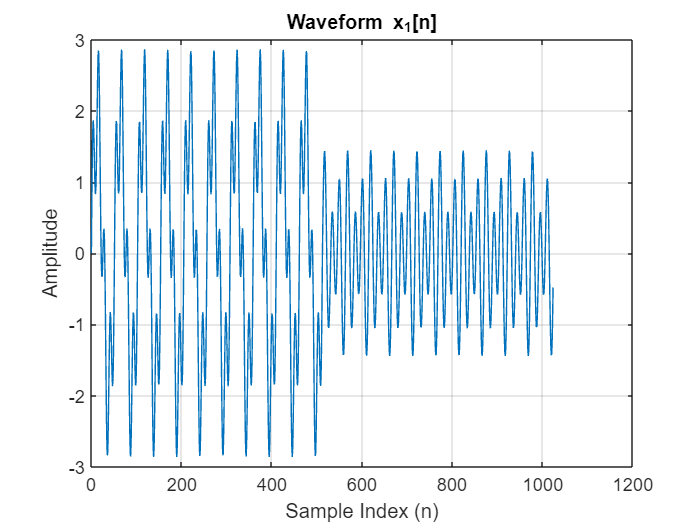

% Plotting x1[n]
figure;
plot(n, x1);
xlabel('Sample Index (n)');
ylabel('Amplitude');
title('Waveform x_{1}[n]');
grid on;

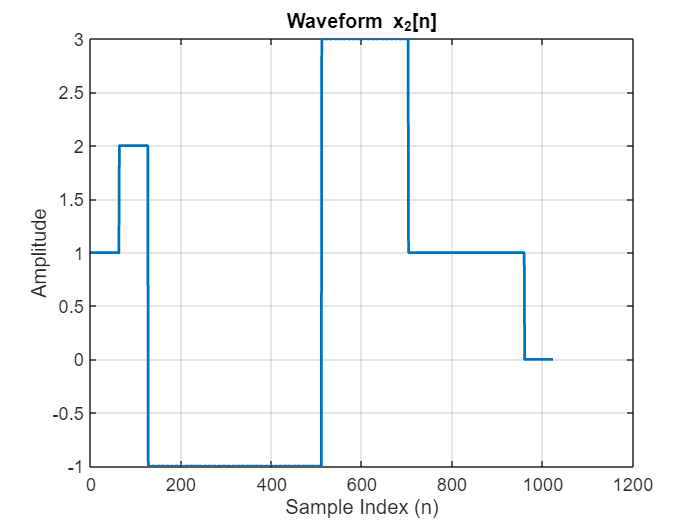

% Plotting x2[n]
plot(n, x2, 'LineWidth', 1.5);
xlabel('Sample Index (n)');
ylabel('Amplitude');
title('Waveform x_{2}[n]');
grid on;

% Add AWGN with 10 dB SNR
SNR = 10;
rng(0);
y1 = awgn(x1, SNR, 'measured');
y2 = awgn(x2, SNR, 'measured');

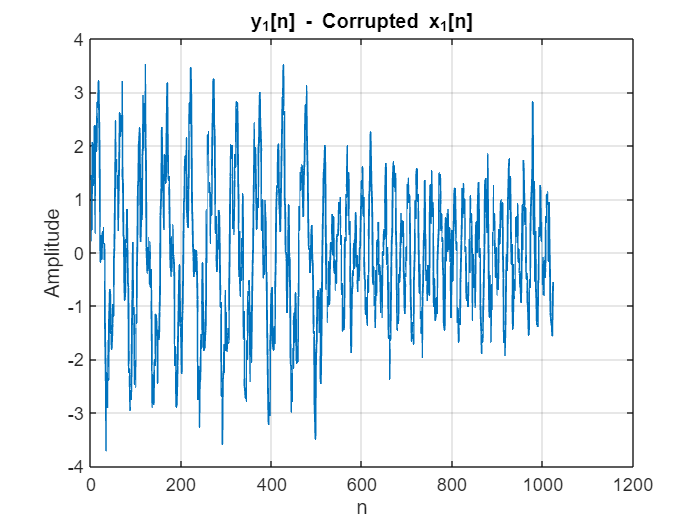

% Plot  y1[n] 
figure;
plot(n, y1, 'LineWidth', 1);
xlabel('n'); ylabel('Amplitude');
title('y_{1}[n] - Corrupted x_{1}[n]');
grid on;

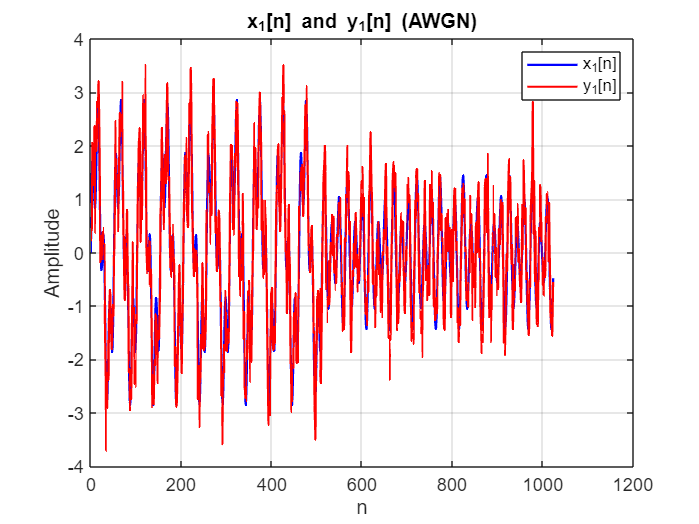

% Plot x1[n] and y1[n] on the same figure
figure;
plot(n, x1, 'b', 'LineWidth', 1.2); hold on;
plot(n, y1, 'r', 'LineWidth', 1.2);
xlabel('n'); ylabel('Amplitude');
title('x_{1}[n] and y_{1}[n] (AWGN)');
legend('x_{1}[n]', 'y_{1}[n]');
grid on;

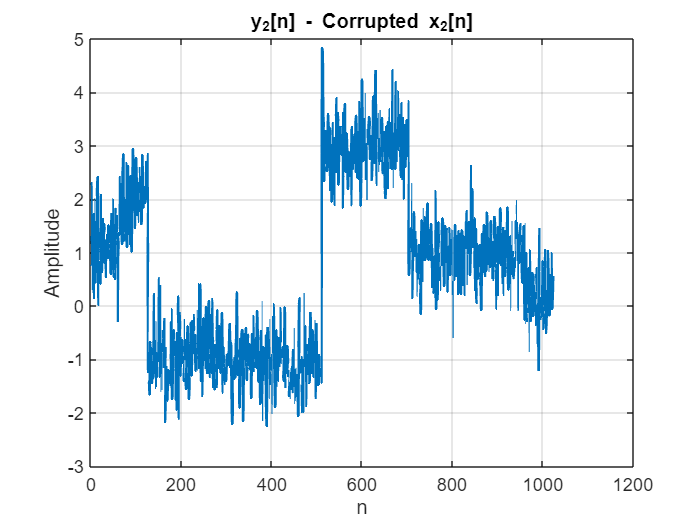

% Plot y2[n] 
figure;
plot(n, y2, 'LineWidth', 1.5);
xlabel('n'); ylabel('Amplitude');
title('y_{2}[n] - Corrupted x_{2}[n]');
grid on;

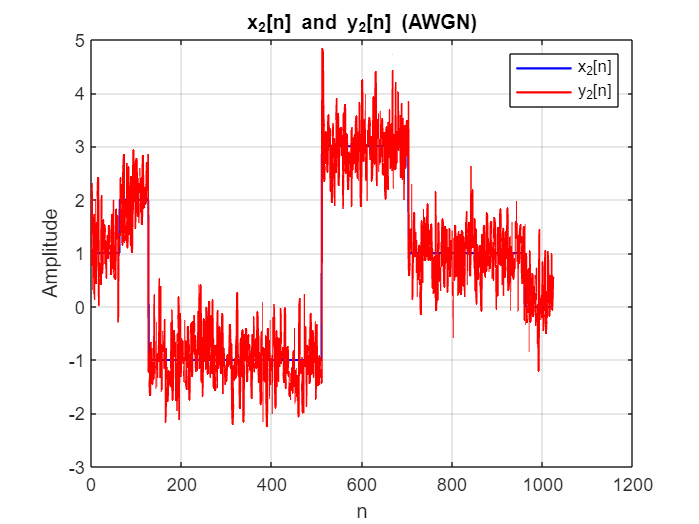

% Plot x2[n] and y2[n] on the same figure
figure;
plot(n, x2, 'b', 'LineWidth', 1.2); hold on;
plot(n, y2, 'r', 'LineWidth', 1.2);
xlabel('n'); ylabel('Amplitude');
title('x_{2}[n] and y_{2}[n] (AWGN)');
legend('x_{2}[n]', 'y_{2}[n]');
grid on;


% Decompose signals with db9 and Haar wavelets
[coeffs_y1_db9, l_y1_db9] = wavedec(y1, 10, 'db9');
[coeffs_y1_haar, l_y1_haar] = wavedec(y1, 10, 'haar');
[coeffs_y2_db9, l_y2_db9] = wavedec(y2, 10, 'db9');
[coeffs_y2_haar, l_y2_haar] = wavedec(y2, 10, 'haar');

% Calculate and sort the magnitude of coefficients in descending order
coeffs_y1_db9_sorted = sort(abs(coeffs_y1_db9), 'descend');
coeffs_y1_haar_sorted = sort(abs(coeffs_y1_haar), 'descend');
coeffs_y2_db9_sorted = sort(abs(coeffs_y2_db9), 'descend');
coeffs_y2_haar_sorted = sort(abs(coeffs_y2_haar), 'descend');

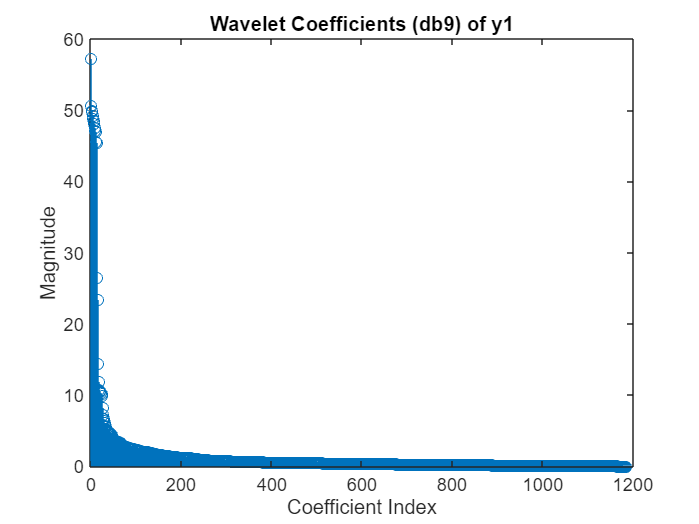

% Plot for y1 with db9
figure;
stem(coeffs_y1_db9_sorted);
title('Wavelet Coefficients (db9) of y1');
xlabel('Coefficient Index');
ylabel('Magnitude');

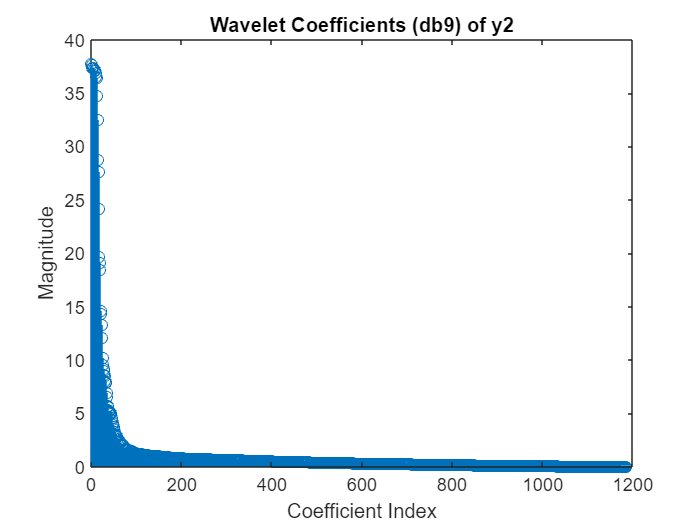

% Plot for y2 with db9
figure;
stem(coeffs_y2_db9_sorted);
title('Wavelet Coefficients (db9) of y2');
xlabel('Coefficient Index');
ylabel('Magnitude');

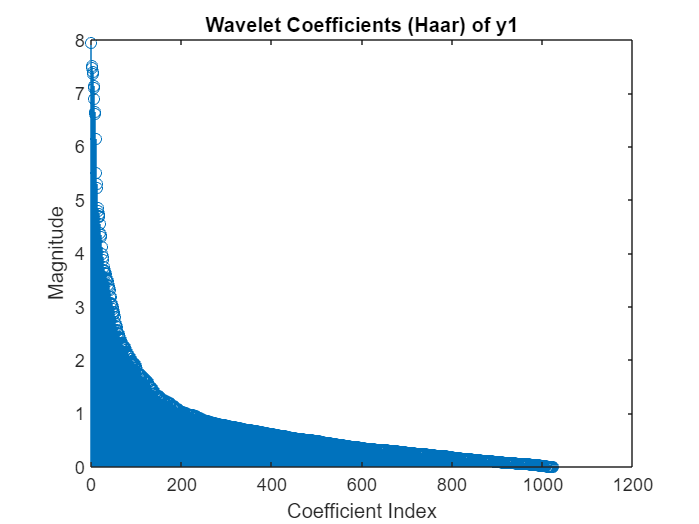

% Plot for y1 with Haar
figure;
stem(coeffs_y1_haar_sorted);
title('Wavelet Coefficients (Haar) of y1');
xlabel('Coefficient Index');
ylabel('Magnitude');

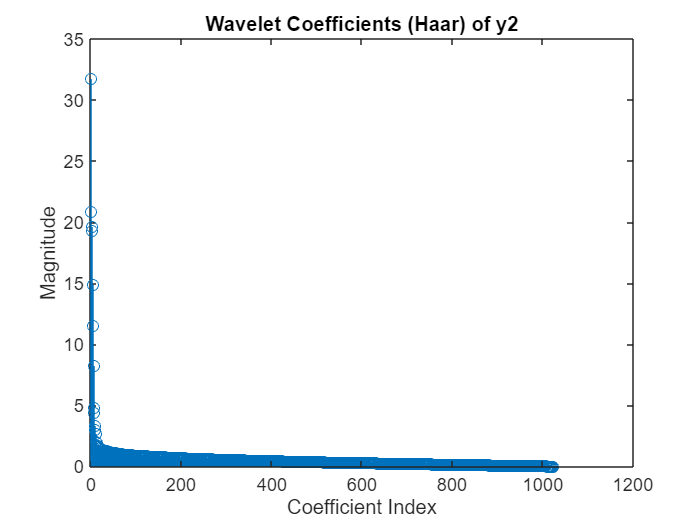

% Plot for y2 with Haar
figure;
stem(coeffs_y2_haar_sorted);
title('Wavelet Coefficients (Haar) of y2');
xlabel('Coefficient Index');
ylabel('Magnitude');

% threshold for y1 with db9
thresh_y1_db9 = 0.9;

coeffs_y1_db9_denoised = coeffs_y1_db9;
coeffs_y1_db9_denoised(abs(coeffs_y1_db9) < thresh_y1_db9) = 0;

% Reconstruct the signal (y1) from the thresholded coefficients
y1_reconstructed_denoised_db9 = waverec(coeffs_y1_db9_denoised, l_y1_db9, 'db9');

% Calculate the RMSE between the original and denoised signals
rmse_y1_db9 = sqrt(mean((x1 - y1_reconstructed_denoised_db9).^2));
disp(['Root Mean Square Error (RMSE) y1 db9: ', num2str(rmse_y1_db9)]);

Root Mean Square Error (RMSE) y1 db9: 0.29202


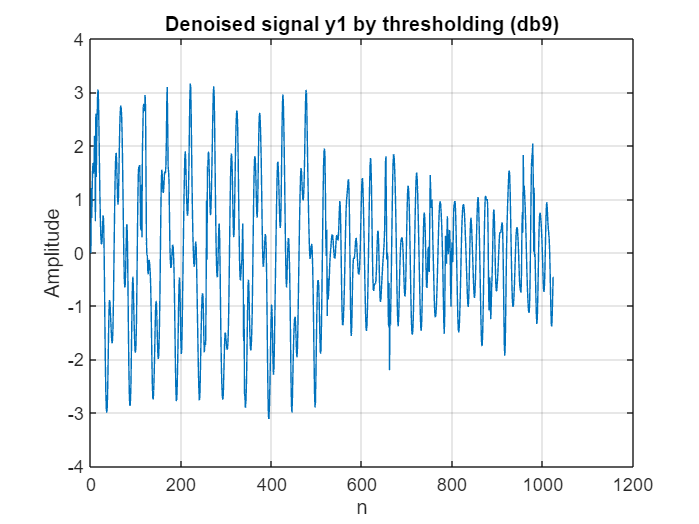

% Plot for y1 with db9 denoised
figure;
plot(n, y1_reconstructed_denoised_db9);
xlabel('n'); ylabel('Amplitude');
title('Denoised signal y1 by thresholding (db9)');
grid on;

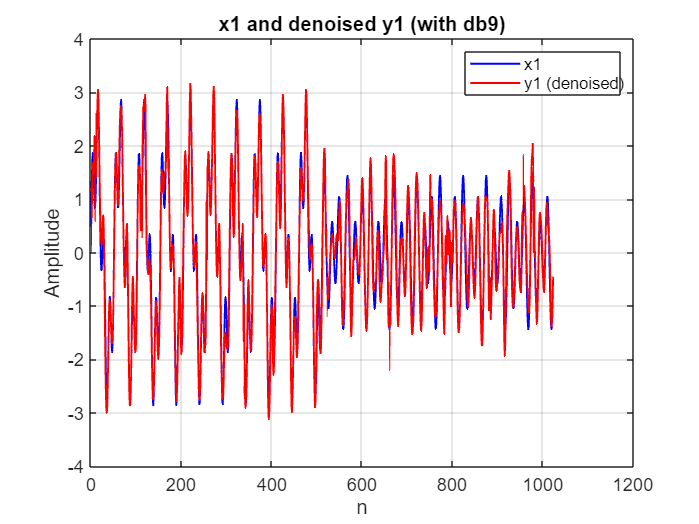

% Plot x1 and denoised y1 on the same figure
figure;
plot(n, x1, 'b', 'LineWidth', 1); hold on;
plot(n, y1_reconstructed_denoised_db9, 'r', 'LineWidth', 1);
xlabel('n'); ylabel('Amplitude');
title('x1 and denoised y1 (with db9)');
legend('x1', 'y1 (denoised)');
grid on;

% threshold for y2 with db9
thresh_y2_db9 = 1.5;

coeffs_y2_db9_denoised = coeffs_y2_db9;
coeffs_y2_db9_denoised(abs(coeffs_y2_db9) < thresh_y2_db9) = 0;

% Reconstruct the signal (y1) from the thresholded coefficients
y2_reconstructed_denoised_db9 = waverec(coeffs_y2_db9_denoised, l_y2_db9, 'db9');

% Calculate the RMSE between the original and denoised signals
rmse_y2_db9 = sqrt(mean((x2 - y2_reconstructed_denoised_db9).^2));
disp(['Root Mean Square Error (RMSE) y2 db9: ', num2str(rmse_y2_db9)]);

Root Mean Square Error (RMSE) y2 db9: 0.26924


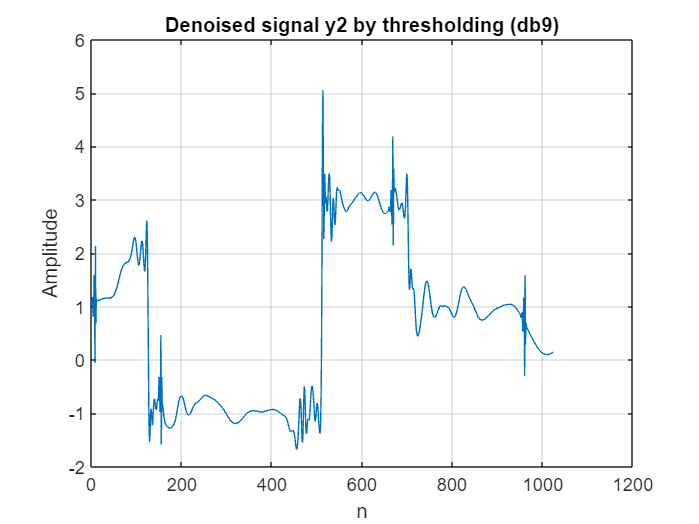

% Plot for y2 with db9 denoised
figure;
plot(n, y2_reconstructed_denoised_db9);
xlabel('n'); ylabel('Amplitude');
title('Denoised signal y2 by thresholding (db9)');
grid on;

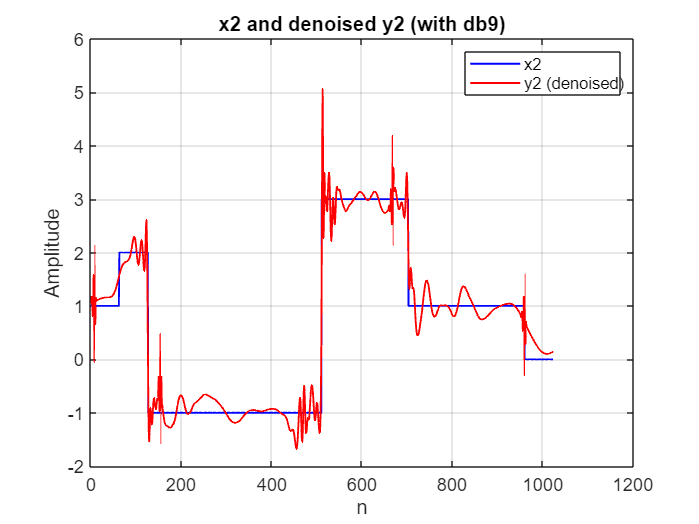

% Plot x2 and denoised y2 on the same figure
figure;
plot(n, x2, 'b', 'LineWidth', 1); hold on;
plot(n, y2_reconstructed_denoised_db9, 'r', 'LineWidth', 1);
xlabel('n'); ylabel('Amplitude');
title('x2 and denoised y2 (with db9)');
legend('x2', 'y2 (denoised)');
grid on;

% threshold for y1 with haar
thresh_y1_haar = 0.25;

coeffs_y1_haar_denoised = coeffs_y1_haar;
coeffs_y1_haar_denoised(abs(coeffs_y1_haar) < thresh_y1_haar) = 0;

% Reconstruct the signal (y1) from the thresholded coefficients
y1_reconstructed_denoised_haar = waverec(coeffs_y1_haar_denoised, l_y1_haar, 'haar');

% Calculate the RMSE between the original and denoised signals
rmse_y1_haar = sqrt(mean((x1 - y1_reconstructed_denoised_haar).^2));
disp(['Root Mean Square Error (RMSE) y1 haar: ', num2str(rmse_y1_haar)]);

Root Mean Square Error (RMSE) y1 haar: 0.38957


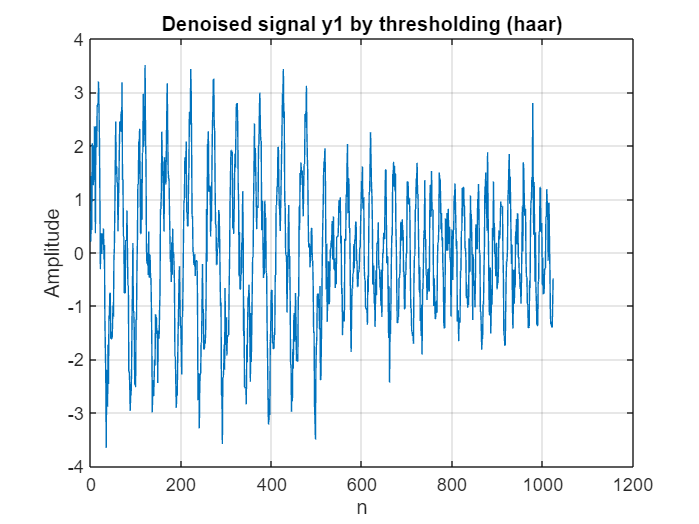

% Plot for y1 with haar denoised
figure;
plot(n, y1_reconstructed_denoised_haar);
xlabel('n'); ylabel('Amplitude');
title('Denoised signal y1 by thresholding (haar)');
grid on;

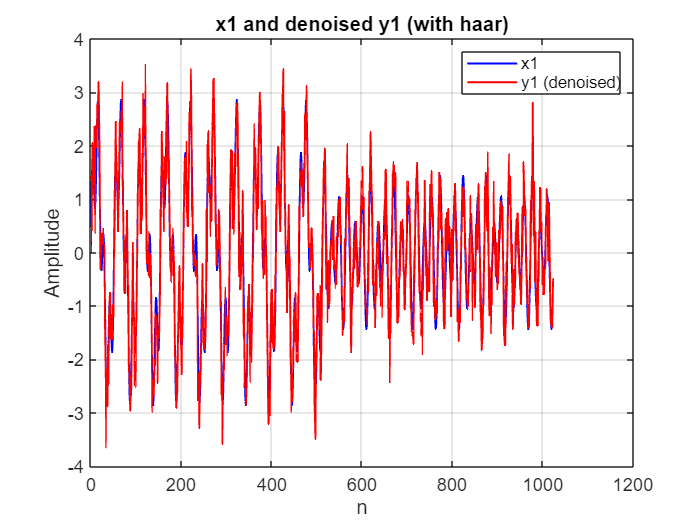

% Plot x1 and denoised y1 on the same figure
figure;
plot(n, x1, 'b', 'LineWidth', 1); hold on;
plot(n, y1_reconstructed_denoised_haar, 'r', 'LineWidth', 1);
xlabel('n'); ylabel('Amplitude');
title('x1 and denoised y1 (with haar)');
legend('x1', 'y1 (denoised)');
grid on;

% threshold for y1 with haar
thresh_y2_haar = 2;

coeffs_y2_haar_denoised = coeffs_y2_haar;
coeffs_y2_haar_denoised(abs(coeffs_y2_haar) < thresh_y2_haar) = 0;

% Reconstruct the signal (y2) from the thresholded coefficients
y2_reconstructed_denoised_haar = waverec(coeffs_y2_haar_denoised, l_y2_haar, 'haar');

% Calculate the RMSE between the original and denoised signals
rmse_y2_haar = sqrt(mean((x2 - y2_reconstructed_denoised_haar).^2));
disp(['Root Mean Square Error (RMSE) y2 haar: ', num2str(rmse_y2_haar)]);

Root Mean Square Error (RMSE) y2 haar: 0.15206


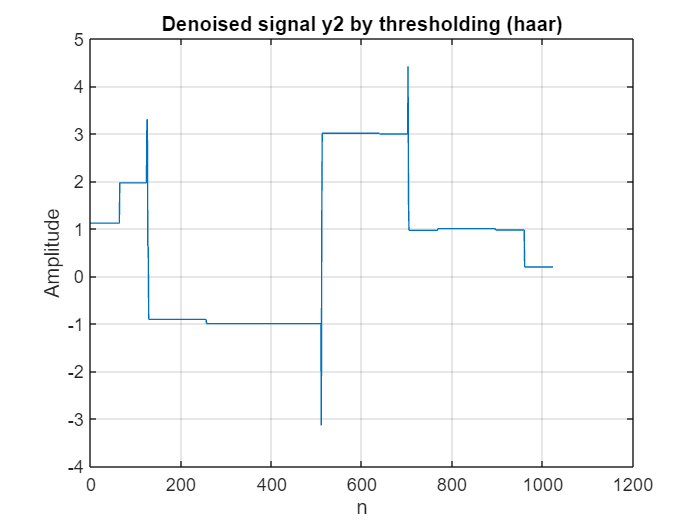

% Plot for y2 with haar denoised
figure;
plot(n, y2_reconstructed_denoised_haar);
xlabel('n'); ylabel('Amplitude');
title('Denoised signal y2 by thresholding (haar)');
grid on;

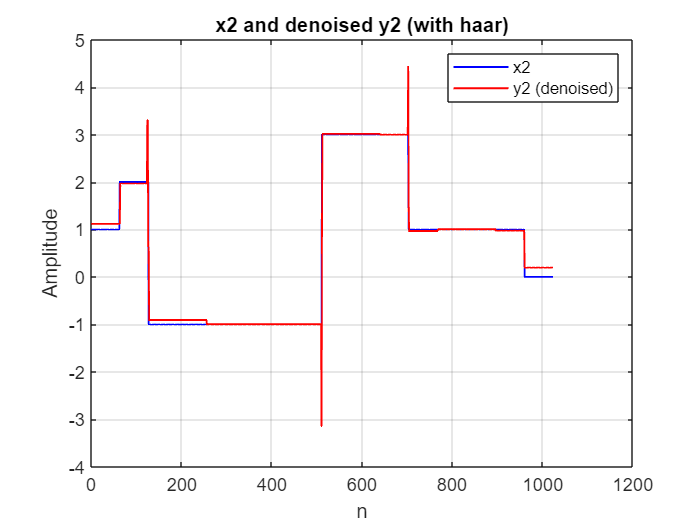

% Plot x2 and denoised y2 on the same figure
figure;
plot(n, x2, 'b', 'LineWidth', 1); hold on;
plot(n, y2_reconstructed_denoised_haar, 'r', 'LineWidth', 1);
xlabel('n'); ylabel('Amplitude');
title('x2 and denoised y2 (with haar)');
legend('x2', 'y2 (denoised)');
grid on;

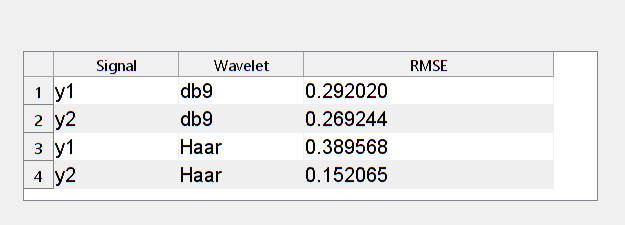

% Define the energy difference data
RMSE_data = {
    'y1', 'db9', sprintf('%.6f', abs(rmse_y1_db9));
    'y2', 'db9', sprintf('%.6f', abs(rmse_y2_db9));
    'y1', 'Haar', sprintf('%.6f', abs(rmse_y1_haar));
    'y2', 'Haar', sprintf('%.6f', abs(rmse_y2_haar));
};

% Create a new figure for the table
fig = figure('Name', 'RMSE', ...
             'NumberTitle', 'off', ...
             'Position', [300, 300, 500, 180]); % Adjust the figure position and size

% Add a uitable to the figure
uitable('Parent', fig, ... % Set the figure as the parent of the table
        'Data', RMSE_data, ...
        'ColumnName', {'Signal', 'Wavelet', 'RMSE'}, ...
        'ColumnWidth', {100, 100, 200}, ...
        'Position', [20, 20, 460, 120], ... % Position and size of the table
        'FontSize', 12); % Optional: Adjust font size for better readability